addpath('./functions');
addpath('./data');

Part 1- Load the CIFAR-10 dataset in Matlab.

In this part I load all the given  training data, test data, and also the lable names.

% Load the meta data containing label names
baches_meta = load("batches.meta.mat");
Lable_names = baches_meta.label_names;


% Load all the five training datasets
dt_train = [];
Labl_train = [];
for i=1:5
    dt = ['data_batch_', num2str(i),'.mat'];
    load(dt)
    % Append data and labels to training dataset and lables
    dt_train = [dt_train; data];
    Labl_train = [Labl_train; labels];
end


% Load the test data
batch = load("test_batch.mat");
dt_test = batch.data;
Labl_test = batch.labels;

Part 2- Preprocess the data 

In this step, I have done the initial preprocessing procedures to prepare my data for processing with Matlab function. 

Firstly, I transformed the image vectors into image matrices and rearranged the width and height through the 

"preprocessing_data" function. Next, I used my "convert_to_categorical" function to convert the labels into categorical

format and change the numerical values to the correspondingcategory names.

 Finally, I illustrate of a sample training data with its label.

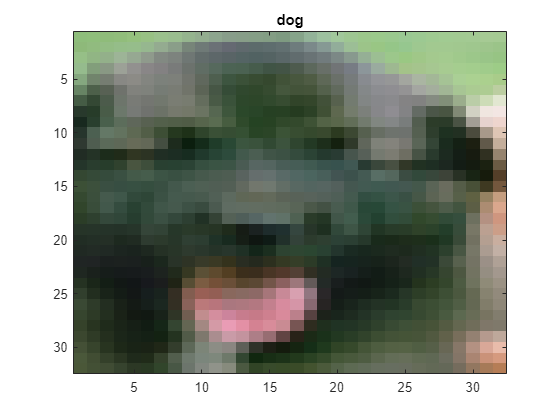

% Reshaping and Permuting the training and test data
[X_train_permute, X_test_permute] = Preprocessing_data(dt_train, dt_test);

% Convert labels to categorical variables
[Y_train_tot, Y_test] = Convert_to_categorical(Labl_train, Labl_test, Lable_names);

% Display an example image and its label
imagesc(X_train_permute(:,:,:,1402)./255)
title(Y_train_tot(1402))

3-  Basic Convolutional Neural Network and train our network

% Define the layers of the CNN model
layers_basic = basic_cnn_classifier()

layers_basic =   14×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   Convolution             32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution             64 3×3 convolutions with stride [1  1] and padding 'same'
     6   ''   ReLU                    ReLU
     7   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Convolution             128 3×3 convolutions with stride [1  1] and padding 'same'
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         128 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         10 fully connected layer
    13

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       12.50% |      10.3623 |          0.0020 |
|       1 |          50 |       00:00:10 |       32.03% |       1.8860 |          0.0020 |
|       1 |         100 |       00:00:11 |       39.84% |       1.7392 |          0.0020 |
|       1 |         150 |       00:00:12 |       35.94% |       1.8056 |          0.0020 |
|       1 |         200 |       00:00:14 |       42.97% |       1.5575 |          0.0020 |
|       1 |         250 |       00:00:15 |       35.94% |       1.6982 |          0.0020 |
|       1 |         300 |  

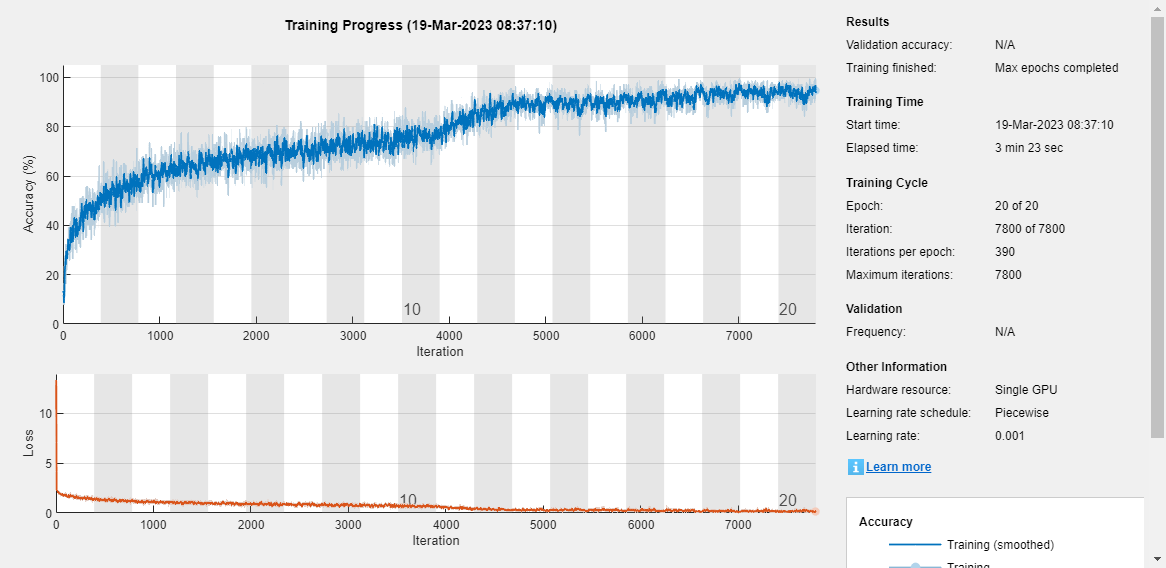


% Define the training options
optimizer_basic = trainingOptions('adam', ...
    'InitialLearnRate', 2e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 128, ...
    'Plots','training-progress');

% Train the CNN model with training data and the defined layers and optimizer
cnn_basic = trainNetwork(X_train_permute, Y_train_tot, layers_basic, optimizer_basic);

4- evaluation of the network

% Calculating the accuracy of the model
Y_pred_basic = cnn_basic.classify (X_test_permute);
accuracy_basic = calculate_acc (Y_pred_basic , Y_test);

disp(['The accuracy of the network is: ' num2str(accuracy_basic) ' %'])

The accuracy of the network is: 64.31 %


5- Improving by normalizing and splitting data

% Normalize the training and testing data
[X_train_norm , X_test_norm] = normalize_data(X_train_permute , X_test_permute);

% Split the training data into training and validation sets
[X_train ,Y_train , X_val, Y_val] = train_val_split(X_train_norm , Y_train_tot);

% Define the layers of the improved CNN
layers_improved = cnn_classifier()

layers_improved =   17×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   Convolution             32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   Convolution             64 3×3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   ''   Convolution             128 3×3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU                    ReLU

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        6.25% |       15.85% |       2.5384 |       7.4415 |          0.0020 |
|       1 |          50 |       00:00:05 |       41.41% |       40.95% |       1.7654 |       1.6204 |          0.0020 |
|       1 |         100 |       00:00:06 |       54.69% |       49.69% |       1.2389 |       1.4249 |          0.0020 |
|       1 |         150 |       00:00:08 |       42.19% |       52.37% |       1.4505 |   

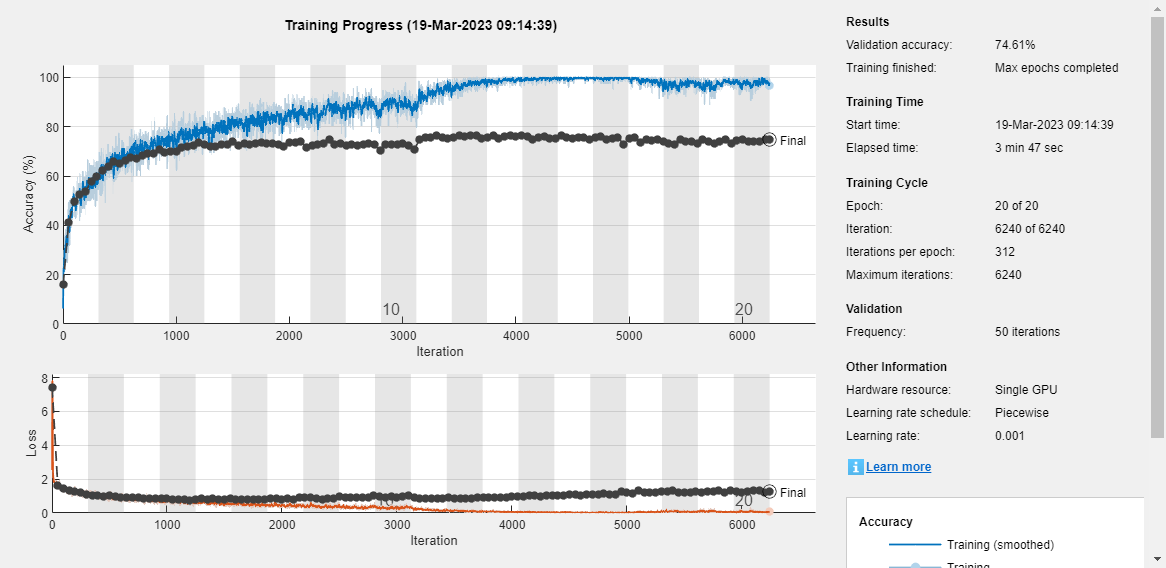


% Define the training options
optimizer_improved = trainingOptions('adam', ...
    'InitialLearnRate', 2e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'ValidationData', {X_val, Y_val}, ...
    'LearnRateDropFactor', 0.5, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 128, ...
    'Plots','training-progress');
cnn_improved = trainNetwork(X_train, Y_train, layers_improved, optimizer_improved);

% Calculating the accuracy of the model
Y_pred_improved = cnn_improved.classify(X_test_norm);

accuracy_improved = calculate_acc(Y_pred_improved,Y_test);

con_matrix_improved = confusionmat(Y_test, Y_pred_improved);

disp(['The accuracy of the network is: ' num2str(accuracy_improved) ' %'])

The accuracy of the network is: 74.93 %


6- Ablation study

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        7.03% |        9.80% |       2.7612 |      11.9639 |          0.0020 |
|       1 |          50 |       00:00:04 |       30.47% |       34.56% |       1.8948 |       1.8038 |          0.0020 |
|       1 |         100 |       00:00:05 |       39.84% |       38.60% |       1.6682 |       1.6188 |          0.0020 |
|       1 |         150 |       00:00:07 |       39.84% |       45.23% |       1.5099 |   

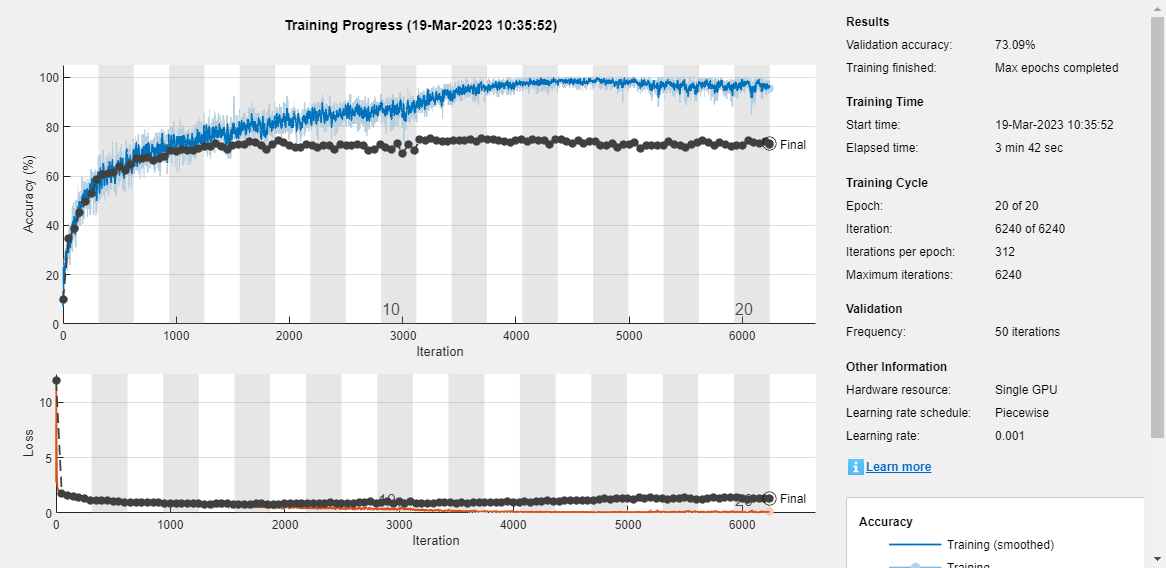

% Train the model without normalization
[X_train_nn ,Y_train_nn , X_val_nn, Y_val_nn] = train_val_split(X_train_permute , Y_train_tot);

optimizer_nonorm = trainingOptions('adam', ...
    'InitialLearnRate', 2e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'ValidationData', {X_val_nn, Y_val_nn}, ...
    'LearnRateDropFactor', 0.5, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 128, ...
    'Plots','training-progress');

cnn_nonorm = trainNetwork(X_train_nn, Y_train_nn, layers_improved, optimizer_nonorm);


Y_pred_nonorm = cnn_nonorm.classify(X_test_permute);

accuracy_nonorm= calculate_acc(Y_pred_nonorm,Y_test);

con_matrix_nonorm = confusionmat(Y_test, Y_pred_nonorm);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       10.94% |       2.5764 |          0.0020 |
|       1 |          50 |       00:00:03 |       31.25% |       1.8528 |          0.0020 |
|       1 |         100 |       00:00:04 |       45.31% |       1.4421 |          0.0020 |
|       1 |         150 |       00:00:06 |       60.94% |       1.1803 |          0.0020 |
|       1 |         200 |       00:00:07 |       60.16% |       1.0821 |          0.0020 |
|       1 |         250 |       00:00:09 |       52.34% |       1.2351 |          0.0020 |
|       1 |         300 |  

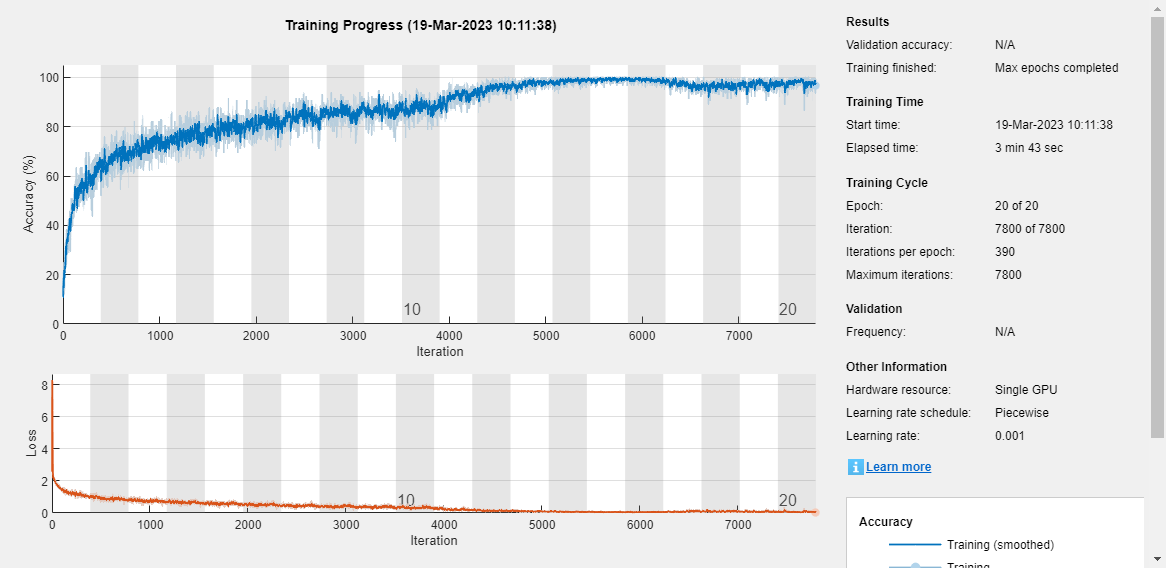


% Train the model without splitting training data 

cnn_nosplit = trainNetwork(X_train_norm, Y_train_tot, layers_improved, optimizer_basic);

Y_pred_nosplit = cnn_nosplit.classify(X_test_norm);
accuracy_nosplit= calculate_acc(Y_pred_nosplit,Y_test);
con_matrix_nosplit = confusionmat(Y_test, Y_pred_nosplit);

% Train the model without bacthnormalizer layers in cnn
layers_nobatchnorm = basic_cnn_classifier()

layers_nobatchnorm =   14×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   Convolution             32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution             64 3×3 convolutions with stride [1  1] and padding 'same'
     6   ''   ReLU                    ReLU
     7   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Convolution             128 3×3 convolutions with stride [1  1] and padding 'same'
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         128 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         10 fully connected layer


Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        8.59% |       10.52% |       2.3393 |       2.7471 |          0.0020 |
|       1 |          50 |       00:00:04 |       42.19% |       40.49% |       1.6489 |       1.6522 |          0.0020 |
|       1 |         100 |       00:00:05 |       39.84% |       47.21% |       1.5747 |       1.4543 |          0.0020 |
|       1 |         150 |       00:00:07 |       54.69% |       49.31% |       1.3361 |   

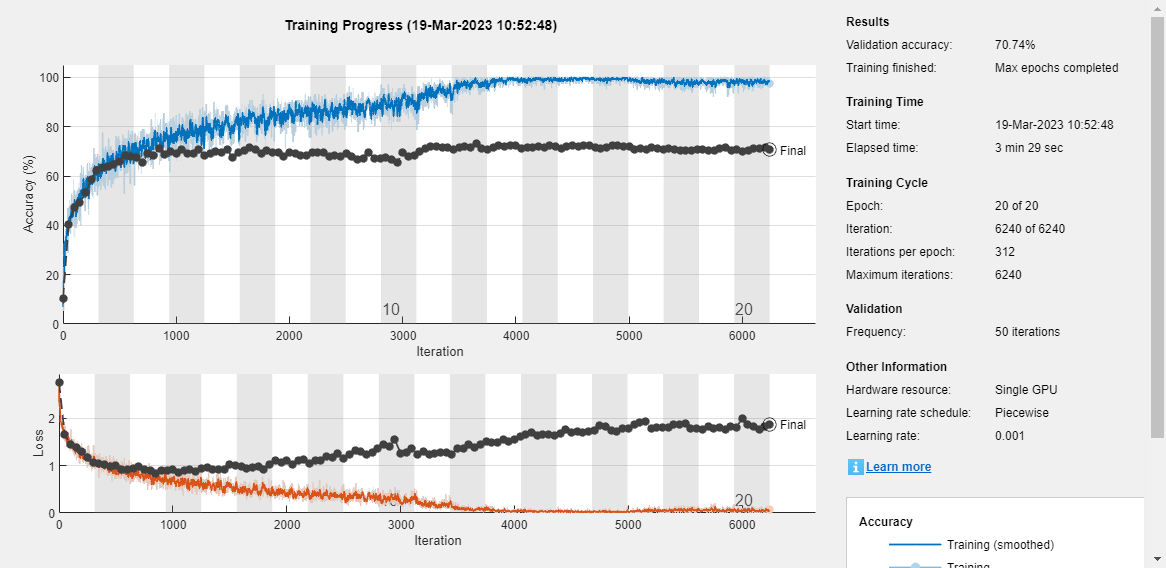

cnn_nobatch = trainNetwork(X_train, Y_train, layers_nobatchnorm, optimizer_improved);

Y_pred_nobatch = cnn_nobatch.classify(X_test_norm);
accuracy_nobatch = calculate_acc(Y_pred_nobatch,Y_test);
con_matrix_nobatch = confusionmat(Y_test, Y_pred_nobatch);

% Display the results
fprintf("Final Model Accuracy: %.2f%%\n", accuracy_improved);

Final Model Accuracy: 74.93%


disp("Final Model Confusion Matrix:");

Final Model Confusion Matrix:


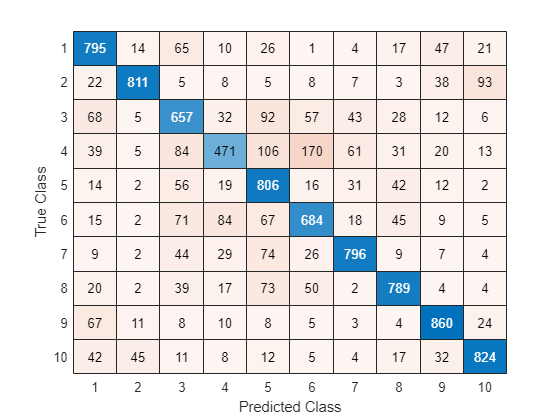

confusionchart(con_matrix_improved)

% disp(con_matrix_final);

fprintf("Model Accuracy without normalization: %.2f%%\n", accuracy_nonorm);

Model Accuracy without normalization: 73.13%


disp("Confusion Matrix for Model without normalization:");

Confusion Matrix for Model without normalization:


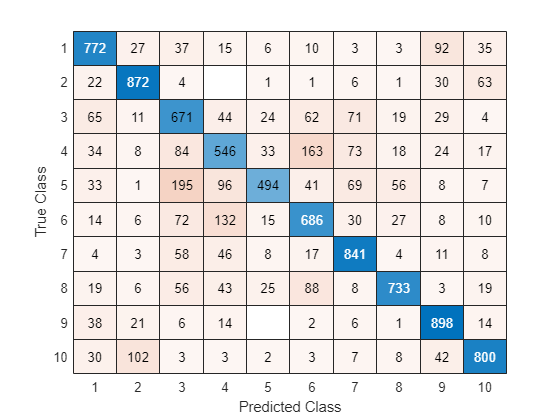

confusionchart(con_matrix_nonorm)

% disp(con_matrix_nonorm);

fprintf("Model without splitting training data: %.2f%%\n", accuracy_nosplit);

Model without splitting training data: 74.69%


disp("Confusion Matrix for Model without splitting training data:");

Confusion Matrix for Model without splitting training data:


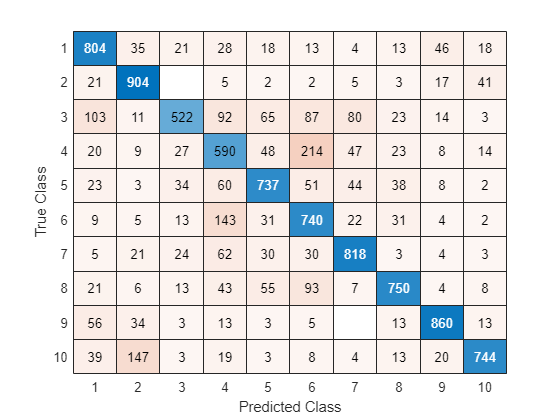

confusionchart(con_matrix_nosplit)

% disp(con_matrix_nosplit);

fprintf("Accuracy of the model without Batch Normalization: %.2f%%\n", accuracy_nobatch);

Accuracy of the model without Batch Normalization: 70.82%


disp(" Confusion Matrix of the model without Batch Normalization:");

 Confusion Matrix of the model without Batch Normalization:


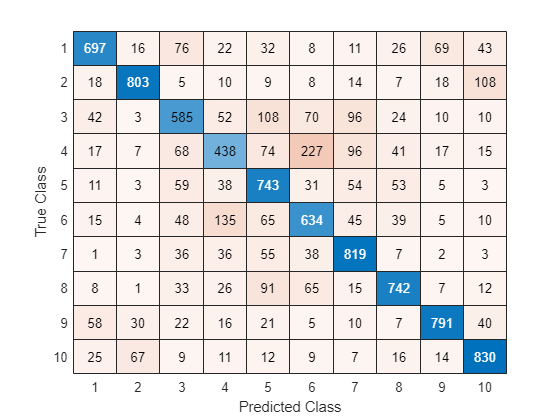

confusionchart(con_matrix_nobatch)

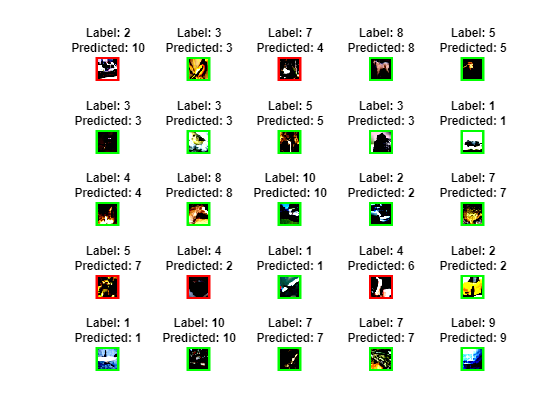

num_img = 25;  % number of images to from the test set
indices = randperm(numel(Labl_test), num_img); % select 20 indices from the test set

for i = 1:5
    for j = 1:5

        subplot(5, 5, (i-1)*5+j);
        index = indices((i-1)*5+j);

        % check whether the predicted is correct and define 
        % border color for wrong and correct predictions

        if Y_pred_improved(index) == Y_test(index)
            border_color = 'g';  
        else
            border_color = 'r'; 
        end
        
        % Adding green or red border to the current test image
        image_with_border = insertShape(X_test_norm(:,:,:,index), 'rectangle', [1 1 32 32], 'LineWidth', 5, 'Color', border_color);

        % Display the image with a border and the corresponding label
        imshow(image_with_border);
        title(sprintf('Label: %d\nPredicted: %d', Y_test(index), Y_pred_improved(index)));
    end
end